## Capture Stereo Images

To simulatneously capture the images from Left and Right webcam camera respectively arranged in a Stereo setup.

% To see the lsit of available webcams
webcamlist

cam1 = webcam(2)
cam2 = webcam(3)

preview(cam1)
preview(cam2)

% Output path to directory where you like to save the captured images
output_image_path = "..\Stereo Images";
count = 1

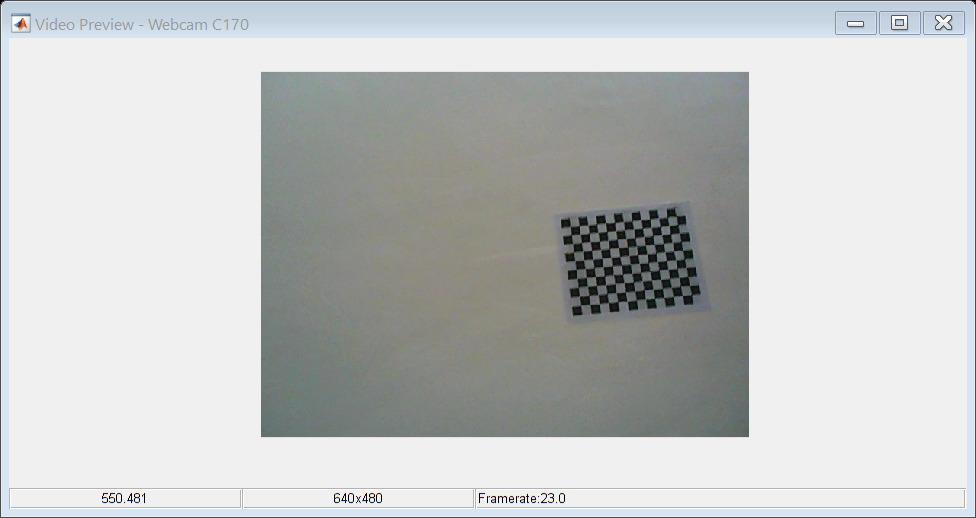

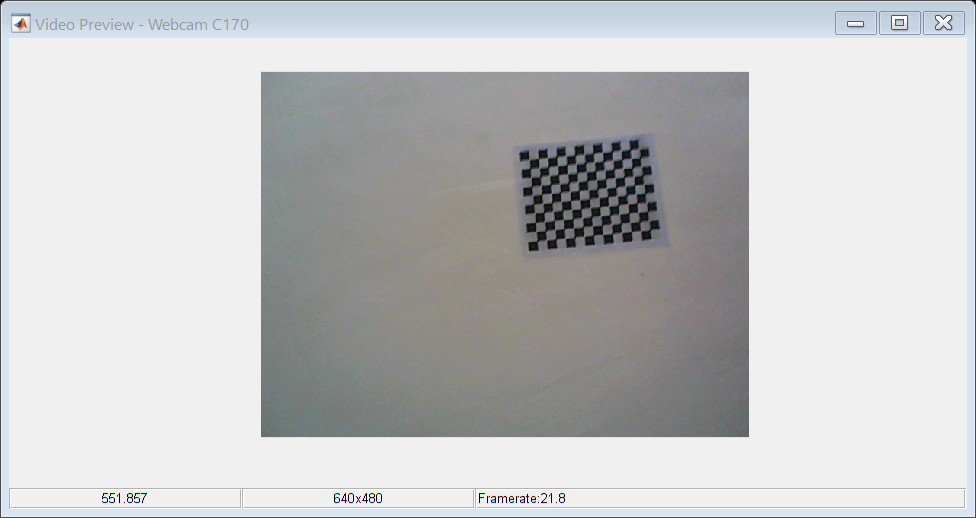

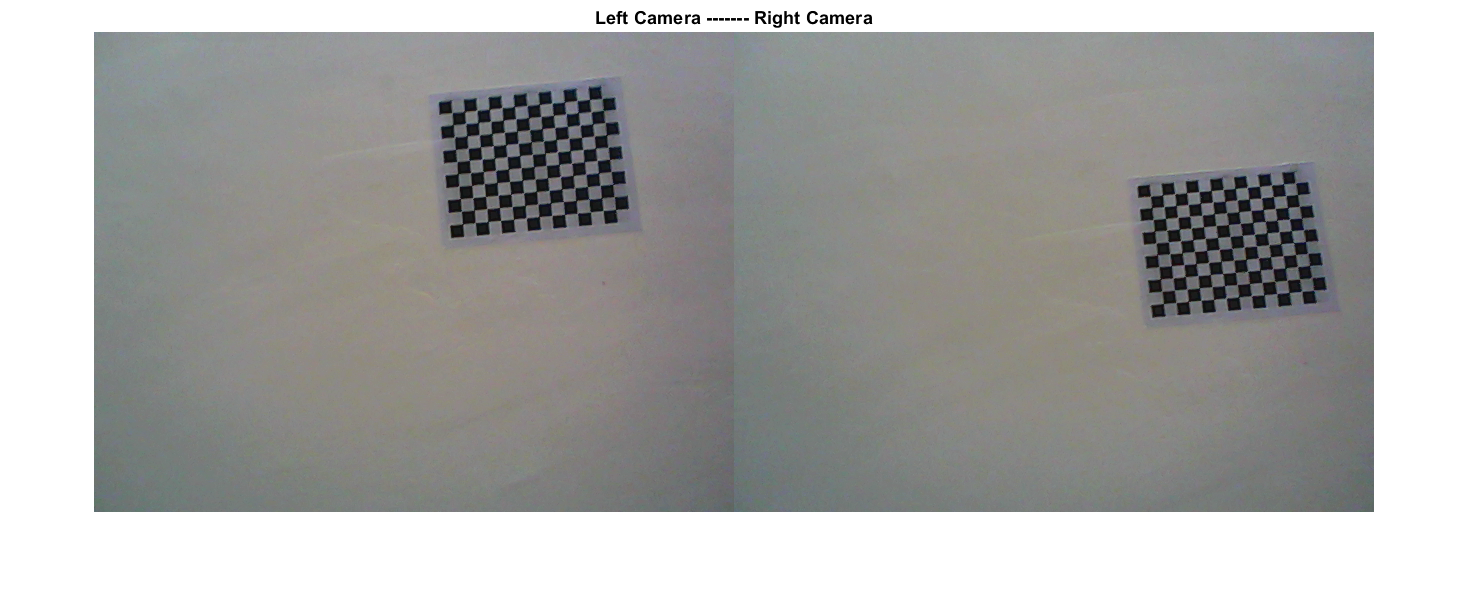

% Run the cell iteratively to capture the left and right view images from diffent
% perspective while rotating or translating a stereo camera setup
img1 = snapshot(cam1);
imwrite(img1, strcat(output_image_path, "\webCam_left\ll_", string(count), ".jpg"), 'jpg')

img2 = snapshot(cam2);
imwrite(img2, strcat(output_image_path, "\webCam_right\rr_", string(count), ".jpg"), 'jpg')

figure; imshow([img1 img2]), title("Left Camera ------- Right Camera");

% figure; imshow(img2), title("Right Camera");
count = count + 1

count = 20